## 1. Overview

### Project purpose

This project aims to simulate and train a Reinforcement Learning (RL) agent to solve the classic control problem of the rotary inverted pendulum, which involves both swing-up and balancing tasks. By leveraging MATLAB's high-fidelity physics simulation, we can select appropriate algorithms and test their performance.

### Target Audience

- Students and researchers studying control systems, robotics, or reinforcement learning.

- Engineers implementing RL-based controllers in simulation or embedded systems.

- Beginners who want to learn practical applications of Simulink, Simscape, and RL Toolbox.

## 2. Requirements

- MATLAB R2023b or newer

- Simulink

- Simscape Multibody

- Reinforcement Learning Toolbox

- Optional: Python 3.9+ with NumPy (for policy export and inference)

## 3. Project Structure

matlab_sim/

├── cad/                     

├── common/                      # Common files used by both agents

│   ├── Rotary_pendulum_DataFile.m

│   ├── Rotary_pendulum.xml

│   └── params.m

├── models/                      # Contains all trained agents, weights, configs

│   ├── Balance/

│   │   ├── agent_balance.m

│   │   ├── env_balance.m

│   │   ├── export_weights_balance.m

│   │   ├── get_action_b.m

│   │   ├── rlSAC_Balance.slx

│   │   ├── train_balance.m

│   │   └── trained_agent_b.mat

│   ├── SwingUp/

│   │   ├── agent_swingup.m

│   │   ├── env_swingup.m

│   │   ├── export_weights_swingup.m

│   │   ├── get_action_su.m

│   │   ├── rlSAC_SwingUp.slx

│   │   ├── train_swingup.m

│   │   └── trained_agent_su.mat

│   └── Test/                   # Reserved for testing agents or configs

│   ├── startup.m

│   └── testAgent.m

├── InvertedPendulum.prj       # MATLAB project file

└── UserGuide.mlx              # Interactive MATLAB Live Script user guide

## 4. How to Use

### Setting and Initiation

- Open **MATLAB R2023b** or newer.

- Open the file `InvertedPendulum.prj` to automatically add all subfolders to the MATLAB path.

**Subfolder Overview**

- `cad/: `Contains CAD files (.step) for the rotary pendulum system.

- `common/: `Includes shared files for both agents:

- `params.m`: global parameters

- `Rotary_pendulum_DataFile.m`: physical constants

- `Rotary_pendulum.xml`: Simscape Multibody XML model

- `models/`Contains training scripts, agents, environments, exported weights:

- `models/Balance/`: SAC agent for stabilization

- `models/SwingUp/`: SAC agent for swing-up

- `models/Test/`: testing configurations or custom agents

- `startup.m`: path setup

- `testAgent.m`: testing exported policy

- `InvertedPendulum.prj`MATLAB project file for easy environment setup

## **5. Step-by-Step **Training and Inference Instructions

To launch the training, please make sure you are in the matlab_sim/ folder to avoid errors.

Before training, we can test the trained policy by running a demo.

Code

mdl = 'rlSAC_Test';
open_system(mdl);  % Open the model GUI
sim(mdl);  

### Swing-Up Agent

#### Objective

The first stage is to train the **Swing-Up SAC Agent** that brings the rotary pendulum from downward to upright.

#### Code and Configuration

**Training Script:**`models/SwingUp/train_swingup.m`

**Environment Definition:**`models/SwingUp/env_swingup.m`

**Agent Configuration:**`models/SwingUp/agent_swingup.m`

#### Actor Network Architecture (Gaussian Policy)

The actor is a stochastic policy outputting both mean and standard deviation of the action using twin-branch feedforward network: 

*Input layer*: Receives observation vector of size numObs

*Share layer*: Fully Connected (8 neurons) → ReLU →  Fully Connected (8 neurons) → ReLU 

*Output layer: *

- Fully Connected  → outputs action mean (Mean branch)

- Fully Connected → `softplus` activation to ensure positive standard deviation (Log Std branch)

#### Critic Architecture (Twin Q-Networks)

*Input branches: *`Observation` → `Fully Connected (64)` → `ReLU`

*Action path: *`Action` → `Fully Connected (64)` → `ReLU`

*Combined pathway:*

- Concatenate the outputs of both paths

- → `Fully Connected (128)` → `ReLU`

- → `Fully Connected (64)` → `ReLU`

- → `Fully Connected (64)` → `ReLU`

- → `Fully Connected (1)` → Outputs Q-value

#### Training Command

To start the training process, press Ctrl + Enter:

Code:

% train_swingup(use_pretrain, max_episodes, max_steps_per_episode, score_averaging_window_length, ...
%               stop_training_value, save_agent_value, use_parallel)
statsSU = train_swingup(false, 500, 200, 1, 200, 150, false);

Successfully exported to file: models/SwingUp/get_action_su.m
Swing-Up agent training completed!


The result of this process may be like this: 

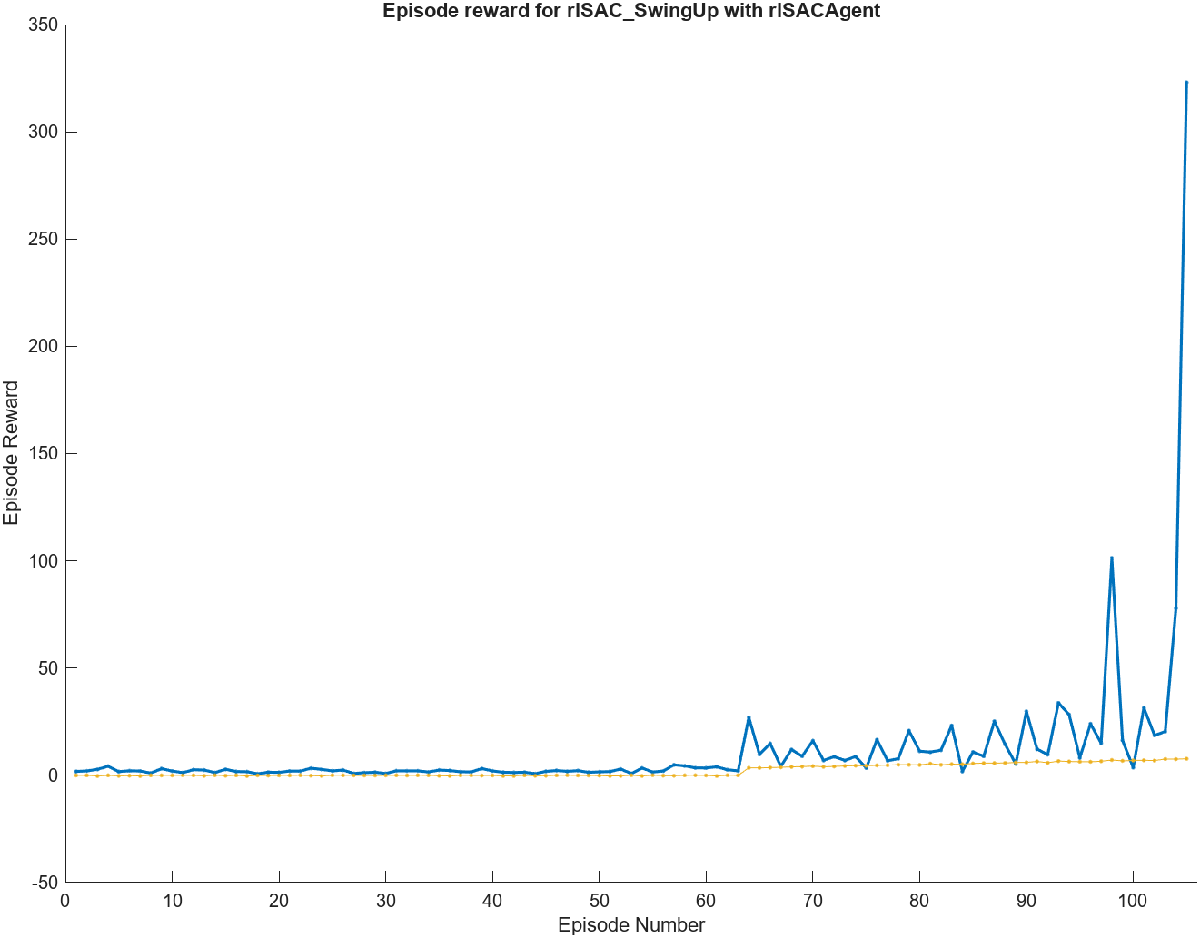

### Balance Agent

#### Objective

The second stage is to train the **Balance SAC Agent** to hold the pendulum in an inverted position.  balance

#### Code and Configuration

**Training Script: **`models/Balance/train_balance.m`

**Environment Definition: **`models/Balance/env_`balance`.m`

**Agent Configuration: **`models/Balance/agent_`balance`.m`

#### Actor Network Architecture (Gaussian Policy)

The actor is a stochastic policy outputting both mean and standard deviation of the action using twin-branch feedforward network: 

*Input layer:* Receives observation vector of size `numObs`.

*Shared hidden layers:*

-  Fully Connected (32 neurons) → ReLU

- Fully Connected (32 neurons) → ReLU

- Fully Connected (32 neurons) → ReLU

*Output branches*

- Fully Connected (`numAct` outputs) → action mean (Mean branch)

- Fully Connected (`numAct` outputs) → softplus activation → action standard deviation (Log-Std branch)

#### Critic Architecture (Twin Q-Networks)

Twin Q-Networks are used to reduce overestimation bias: 

*Observation branch: *

- Fully Connected (64 neurons) → ReLU

*Action branch: *

- Fully Connected (64 neurons) → ReLU

*Merge and subsequent layers: *

- Concatenate(state-feat, action-feat)

- Fully Connected (128 neurons) → ReLU

- Fully Connected (64 neurons) → ReLU

- Fully Connected (64 neurons) → ReLU

- Fully Connected (1 neuron) → Q-value output

### Training Command

To start the training process, press Ctrl + Enter:

Code 

% train_swingup(use_pretrain, max_episodes, max_steps_per_episode, score_averaging_window_length, ...
%               stop_training_value, save_agent_value, use_parallel)
statsB = train_balance(false, 500, 1000, 10, 400, 250, false);

Đã xuất policy Balance → models/Balance/get_action_b.m
Finished training the Balance agent!


The second phase is more challenging than the first one. In this stage, the training process took about 5–6 hours for the agent to learn how to stabilize the pendulum. The result of this training is shown in the image below:

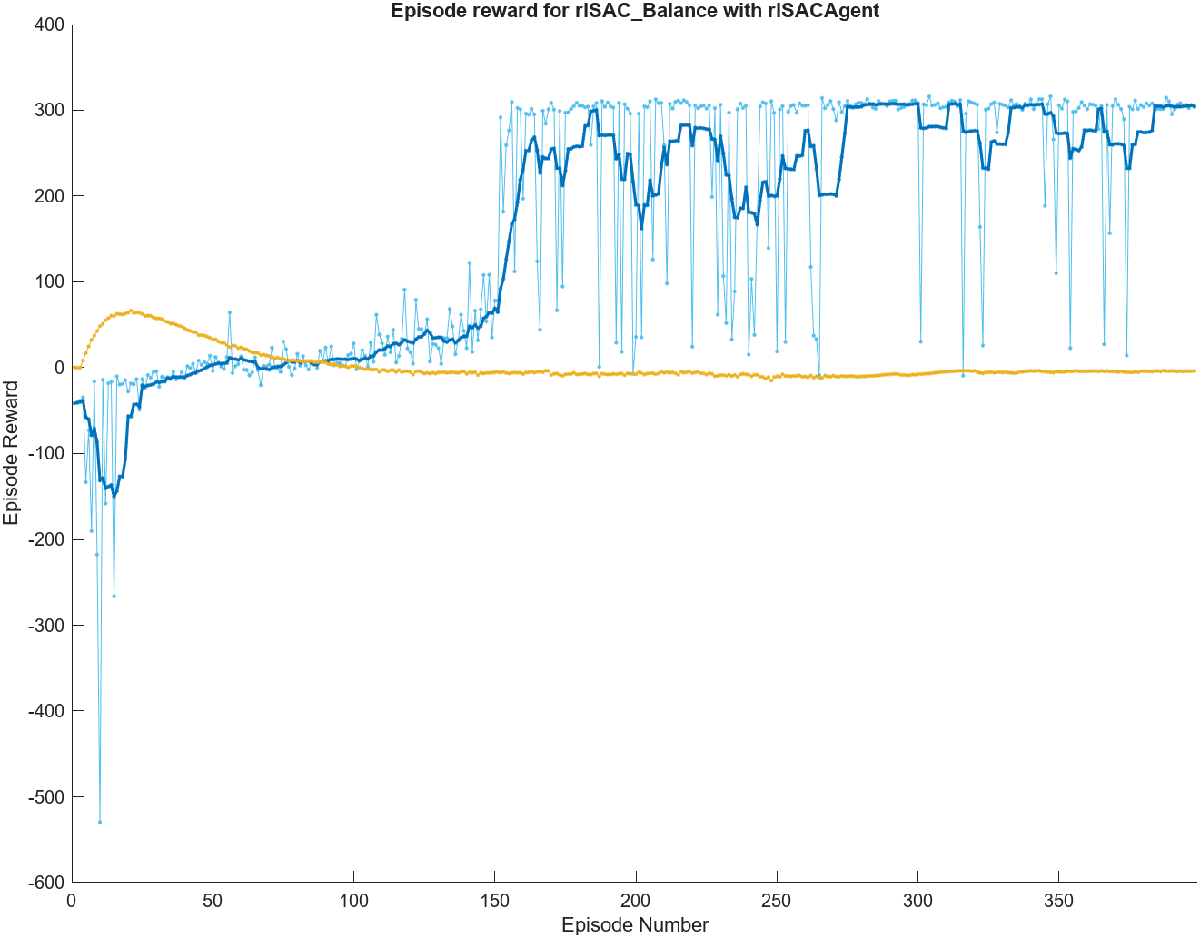

## 6. References

- MathWorks RL Toolbox Documentation

- Soft Actor-Critic (SAC): Haarnoja et al., 2018

- [Simscape Multibody Examples](https://www.mathworks.com/help/physmod/sm/)

## 7. License

This project is licensed under the MIT License. See LICENSE file for details.

If you're using this in commercial products, please review third-party toolbox licenses (e.g., RL Toolbox).

## 8. Contact

- Maintainer: 22134012@student.hcmute.edu.vn

- GitHub: https://github.com/honggquan24/rotary-pendulum-sac-simscape

- Linkdedln: https://www.linkedin.com/in/vo-hong-quan-b50063373/